# Capstone Project : Predicting Demand for Taxi Data

## Objectives

In this report, I **create** a new **model** that predicts **demand around Manhattan and the airports**. This report wll present my findings to Mr. Walker and the business team. I hope this is a compelling final report detailing my findings to get the model implemented. A model that successfully predicts demand will enable Super Taxis to focus on high demand regions and avoid low demand ones, thus improving efficiency and increasing profits.

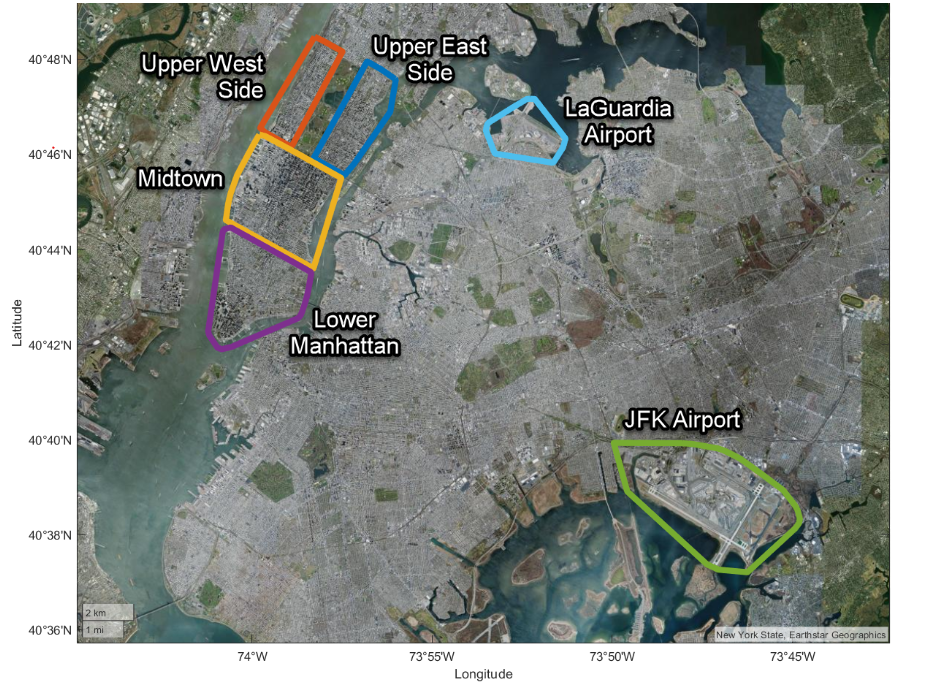

## Data

### Brief Description

Manhattan is often broken into distinct regions: Lower Manhattan, Midtown, Upper East Side, and Upper West Side, as shown in the map above. In addition to the Manhattan regions, my analysis needs to include LaGuardia and JFK airports.

#### Load all taxi data into datastore

taxiDataStore = fileDatastore("/MATLAB Drive/Predictive Modeling and Machine Learning/Taxi Data/yellow_tripdata_2015-*.csv","ReadFcn",@importTaxiDataWithoutCleaning,"UniformRead",true);
taxiAll = readall(taxiDataStore);

### Preprocessing Data

I’ll start by adding the pickup region and drop-off region for each taxi trip to the table of individual rides. After that, I can then start grouping rides by region and hour to find the number of pickups and drop-offs in a given region for a given hour.

- Creating the taxi regions ( Task 1 : Creating the taxi regions )

- Data cleaning ( Task 2 : Data Cleaning )

- Data Restructuring - Creating Group Summary Table ( Task 3 : Data Restructuring - Creating Group Summary Table )

### Description of test data split

For creating machine learning model, we have to split the dataset into a training set and a test set. I split the data into 80% data training and 20% of data testing

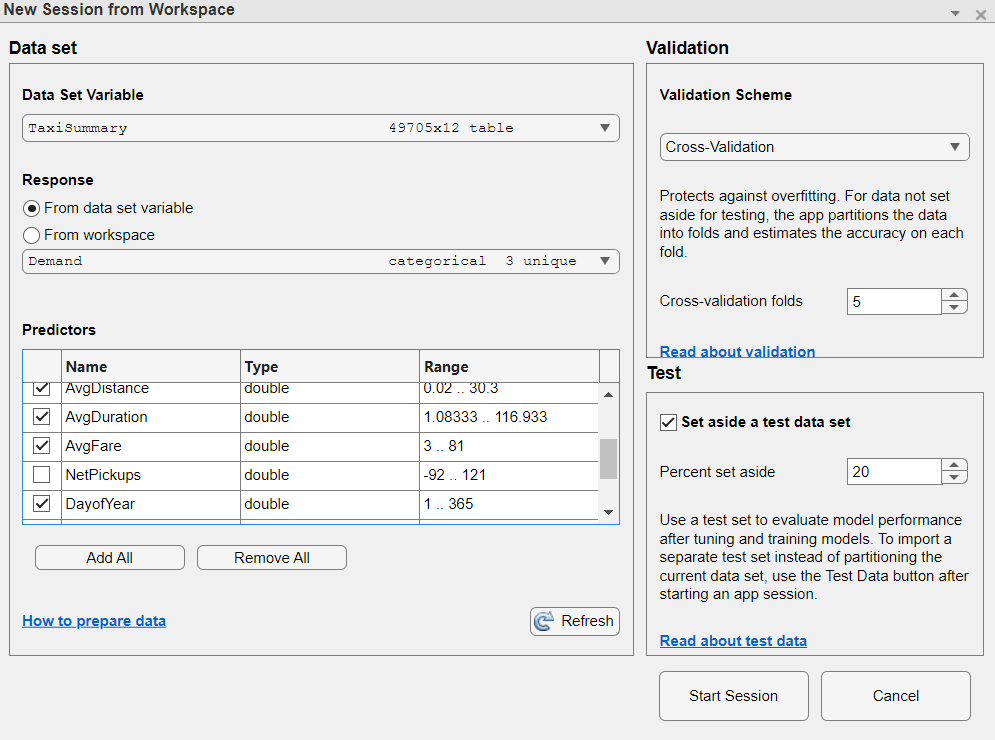

rng(1);
taxiPartitions = cvpartition(height(TaxiSummary),"HoldOut",0.2) % make data testing 20% of all taxi data
taxiTestIdx = test(taxiPartitions);
taxiTest = TaxiSummary(taxiTestIdx,:);
taxiTrainIdx = training(taxiPartitions);
taxiTrain = TaxiSummary(taxiTrainIdx,:);

taxiPartitions = Hold-out cross validation partition
   NumObservations: 49705
       NumTestSets: 1
         TrainSize: 39764
          TestSize: 9941
          IsCustom: 0

### Feature Engineering

After splitting data into a training set and test set, we then create response feature. I have previously computed the number of net pickups (pickups - dropoffs) for each time interval and region and I wanna used this variable to gauge demand for taxi service.

To achieve this goal, I will convert net pickups to a categorical feature, ’Demand’, and use it as the response variable for the classification model(s). To create *Demand*, I convert my numerical net pickup values to categorical values according to the following definitions:

- Net Pickups < 0: ‘Low’ 

- 0 <= Net Pickups < 15: ‘Medium’

- Net Pickups >= 15: ‘High’ 

categories = {'Low', 'Medium', 'High'};
taxiTrain.Demand = discretize(taxiTrain.NetPickups, [-Inf, 0, 15, Inf], 'Categorical', categories);

percentage_high_demand = 100*height(taxiTrain.Demand(taxiTrain.Demand == "High"))/height(taxiTrain.Demand)
groupsummary(taxiTrain,"Demand","none")
taxiTrain_Low = taxiTrain(taxiTrain.Demand == "Low",:);
groupsummary(taxiTrain_Low,"Region","none")

histogram(taxiTrain.Demand)

% Create and evaluate feature
taxiTrain_evaluate = taxiTrain;
taxiTrain_evaluate.DayofYear = day(taxiTrain_evaluate.HourlyBin,'dayofyear');

percentage_high_demand = 16.0874

DayofYear_category = categorical(taxiTrain_evaluate.DayofYear);

ans = 3x2 table
    Demand    GroupCount
    ______    __________

    Low         12355   
    Medium      21012   
    High         6397   


[~,~,p] = crosstab(DayofYear_category,taxiTrain_evaluate.Demand)
p = anova1(taxiTrain_evaluate.DayofYear,taxiTrain_evaluate.Demand)

ans = 6x2 table
         Region          GroupCount
    _________________    __________

    JFK Airport              771   
    LaGuardia Airport        974   
    Lower Manhattan         2342   
    Midtown                 2159   
    Upper East Side         3353   
    Upper West Side         2756   


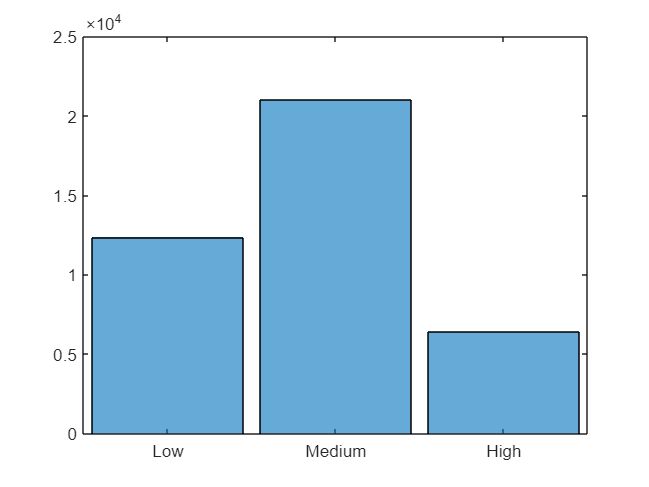

BankHoliday = readtable("/MATLAB Drive/Predictive Modeling and Machine Learning/2015 Bank Holidays.csv")

BankHoliday.DayofYear = day(BankHoliday.Date,'dayofyear')
isHoliday = ismember(taxiTrain_evaluate.DayofYear,BankHoliday.DayofYear);
[~,chi2,p] = crosstab(isHoliday,taxiTrain_evaluate.Demand)

## Modelling

### Objectives

In this section, I try to find the best model for predicts demand around Manhattan and the airports. To find the best model, I will show some of the process of creating model I have tried and how performance of the model is, that is determined by three parameters:

-  Accuracy

- Confusion matrix

- **cMetrics** output (or equivalent)

### Final Model Description

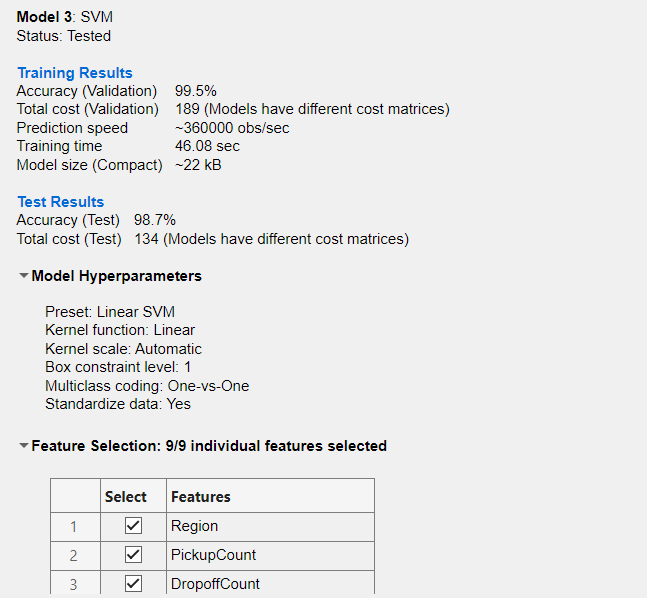 

### Training Description

First, for creating training model, I have created this code

taxiTrain.IsHoliday = isHoliday;
taxiTrain.HourOfDay = hour(taxiTrain_evaluate.HourlyBin);
head(taxiTrain)

p = 0.8363

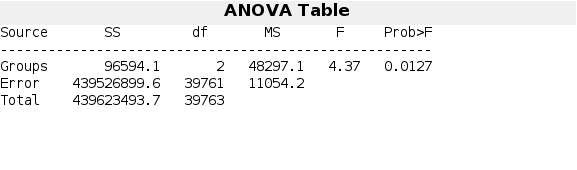

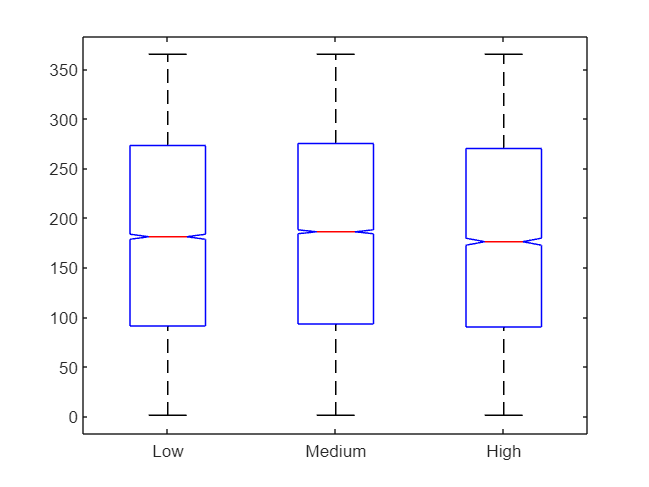

p = 0.0127

taxiTest.DayofYear = day(taxiTest.HourlyBin,'dayofyear');

isHoliday1 = ismember(taxiTest.DayofYear,BankHoliday.DayofYear);
taxiTest.IsHoliday = isHoliday1;

BankHoliday = 12x2 table
       Date                                    Holiday                            
    ___________    _______________________________________________________________

    01-Jan-2015    {'New Year's Day'                                             }
    19-Jan-2015    {'Martin Luther King Jr. Day'                                 }
    16-Feb-2015    {'Washington's Birthday/President's Day'                      }
    03-Apr-2015    {'Good Friday (not federal holiday, but stock markets closed)'}
    25-May-2015    {'Memorial Day'                                               }
    03-Jul-2015    {'Independence Day (observeded)'                              }
    04-Jul-2015    {'Independence Day'                                           }
    07-Sep-2015    {'Labor Day'                                                  }
    12-Oct-2015    {'Columbus Day'                                          

taxiTest.HourOfDay = hour(taxiTest.HourlyBin);

BankHoliday = 12x3 table
       Date                                    Holiday                                DayofYear
    ___________    _______________________________________________________________    _________

    01-Jan-2015    {'New Year's Day'                                             }         1   
    19-Jan-2015    {'Martin Luther King Jr. Day'                                 }        19   
    16-Feb-2015    {'Washington's Birthday/President's Day'                      }        47   
    03-Apr-2015    {'Good Friday (not federal holiday, but stock markets closed)'}        93   
    25-May-2015    {'Memorial Day'                                               }       145   
    03-Jul-2015    {'Independence Day (observeded)'                              }       184   
    04-Jul-2015    {'Independence Day'                                           }       185   
    07-S

head(taxiTest)
TaxiSummary.DayofYear = day(TaxiSummary.HourlyBin,'dayofyear');

chi2 = 11.5734

p = 0.0031

isHoliday_2 = ismember(TaxiSummary.DayofYear,BankHoliday.DayofYear);
TaxiSummary.IsHoliday = isHoliday_2;
TaxiSummary.HourOfDay = hour(TaxiSummary.HourlyBin);
categories = {'Low', 'Medium', 'High'};
TaxiSummary.Demand = discretize(TaxiSummary.NetPickups, [-Inf, 0, 15, Inf], 'Categorical', categories);
head(TaxiSummary)

I tried several method for model type and doing hyperparameter optimization and manipulating cost

#### Results

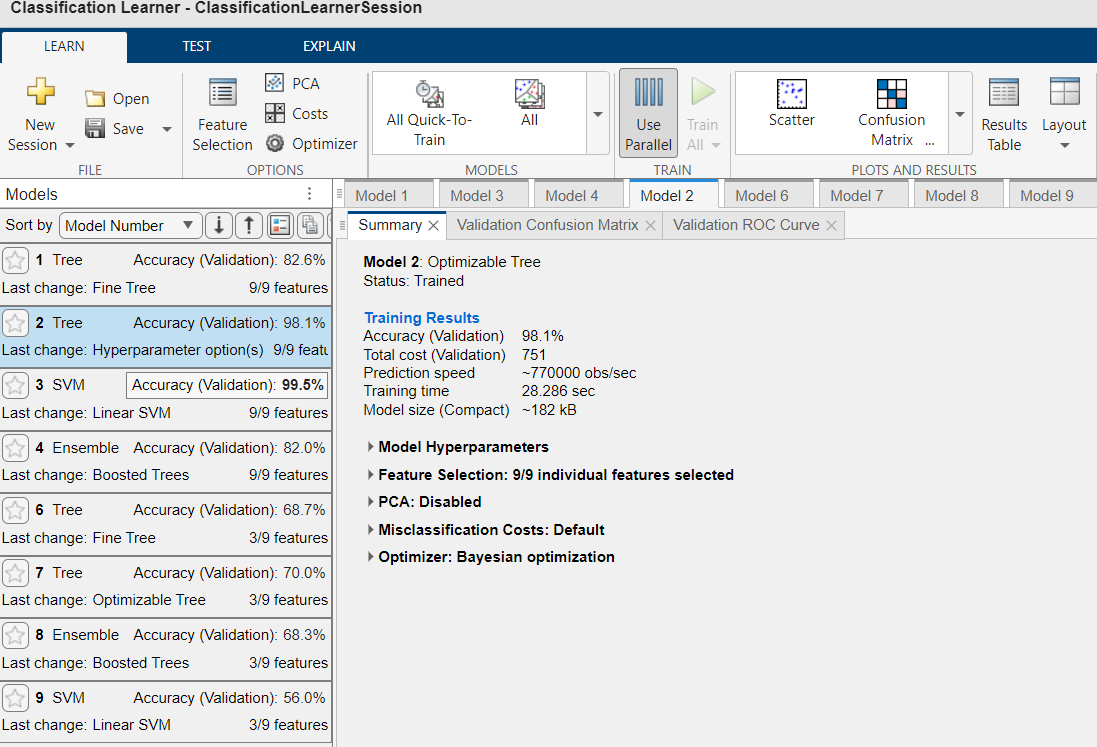

Overall, the training and validation shows us that using only 3 features (Region, IsHoliday, and HourOfDay) are not give great accuracy, while 9 features in group summary table, excluding the NetPickUps give us great accuracy for training and vaidation, about 99.5 % for Linear SVM.

Applying two scenario, 

#### **Scenario 1 **

Start off with a baseline model that emphasizes overall accuracy. Use test data set to verify your modeling results. This model will be useful for analysis and comparison later. It may be also a good way to investigate model types and hyperparameters, class imbalance, and which features are most useful. 

#### **Scenario 2**

Assume the following** taxi deployment strategy **will be followed based on demand: 

- Always go to the nearest High demand region when one is available 

- Go to the nearest Medium demand region if there is no High demand region available 

- Never go to or stay in a Low demand region 

Applying those 2 scenario to analysis of 3 feature as predictor give this results

- Scenario 1

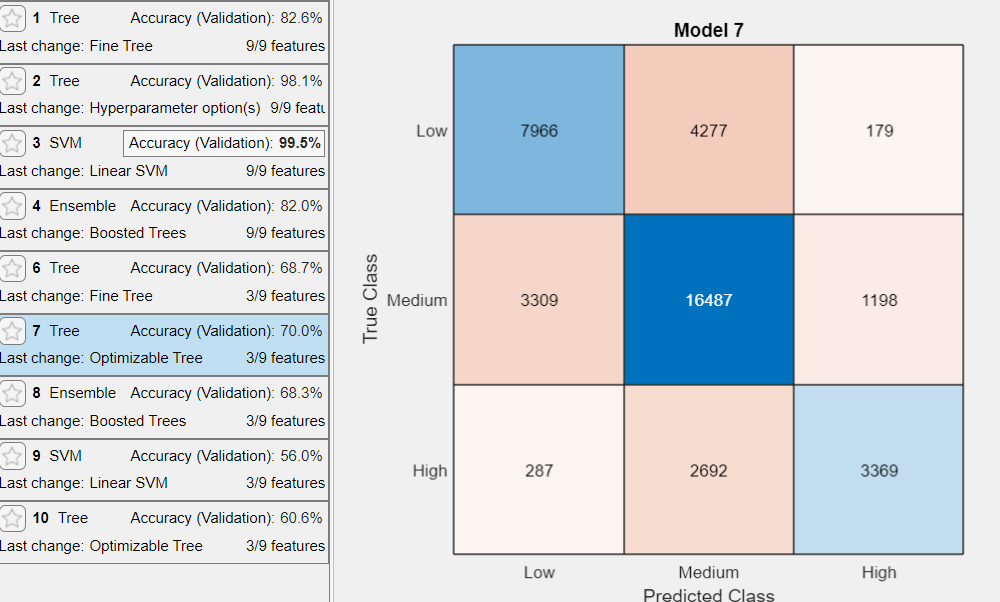

- Scenario 2

    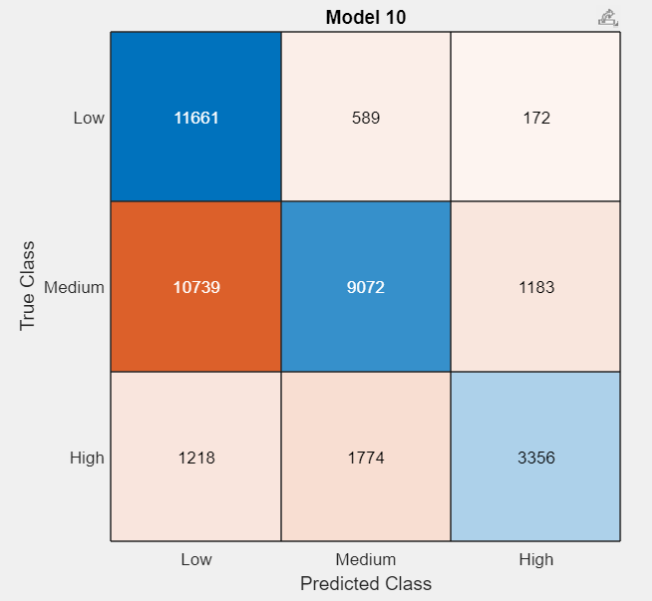

Due to the result, it show that The Scenario 1 model has a lower recall for the Low demand class than the Scenario 2 model.

For scenario 2, I give a bigger cost metric 

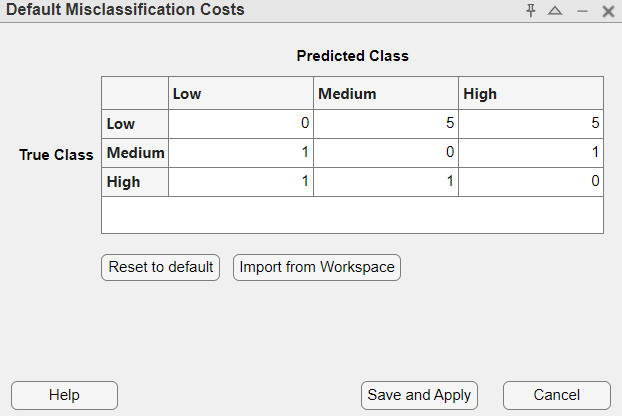

After training and validation, we can also see those analysis from the ROC Curve

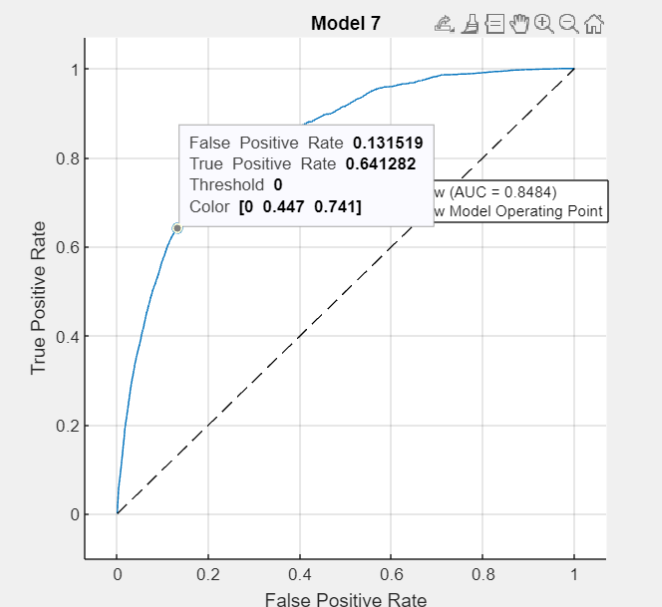     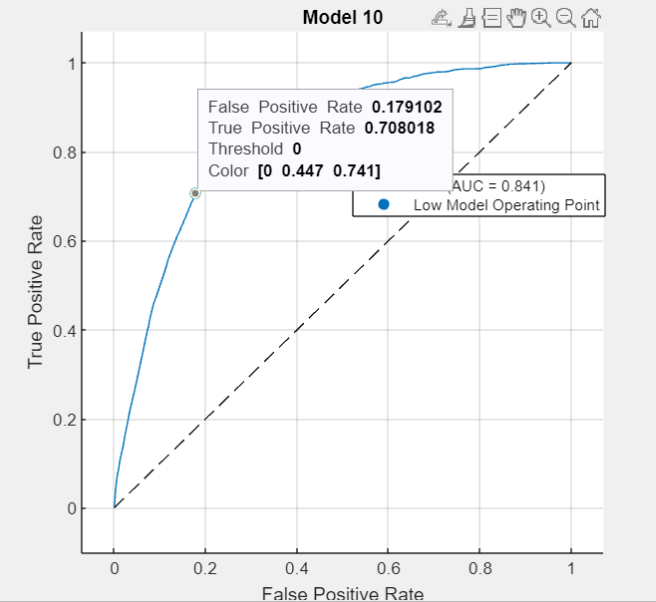

Although the recall is better for scenario 2, it has the drawback that the fallout get bigger.

#### Considering using more feature

After trial and error for predicting the demand (Appendix 2), I think using 9 feature in groupsummary table, except NetPickups because it doesn't mean anything can help us get better result.

As shown in the first training, the accuracy of using finetree and 9 features is 82.6% without hyperparameter tuning or optimazation method.

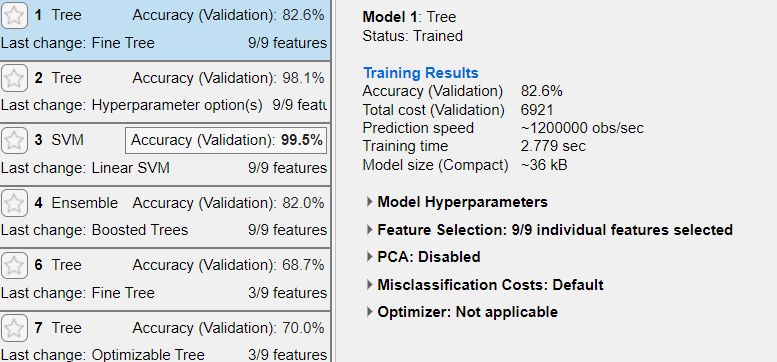

After applying hyperparameter, the model show 98.1 % accuracy, which is better than without hyperparameter. Using different model, such as SVM with 9 features can give 99.5% accuracy for training and validation.

It can predict well to the Demand using those feature

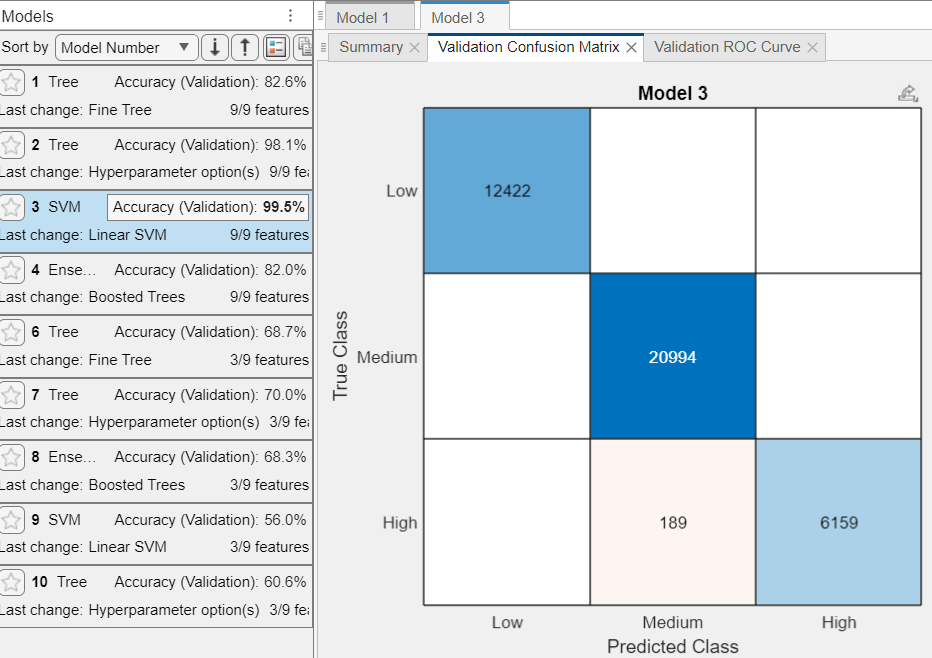

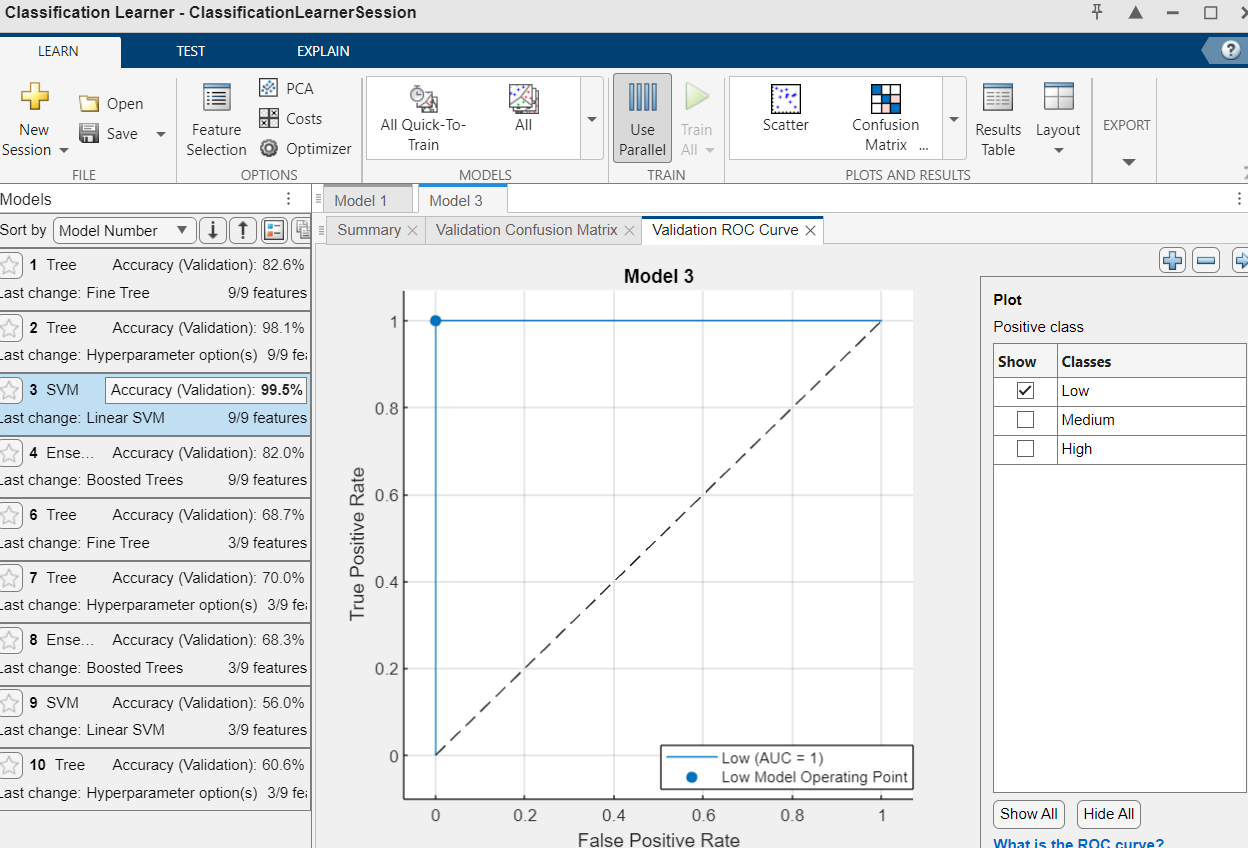

### Test metrics

After doing test, we can see that model 3 give us the best model for predicting the Demand

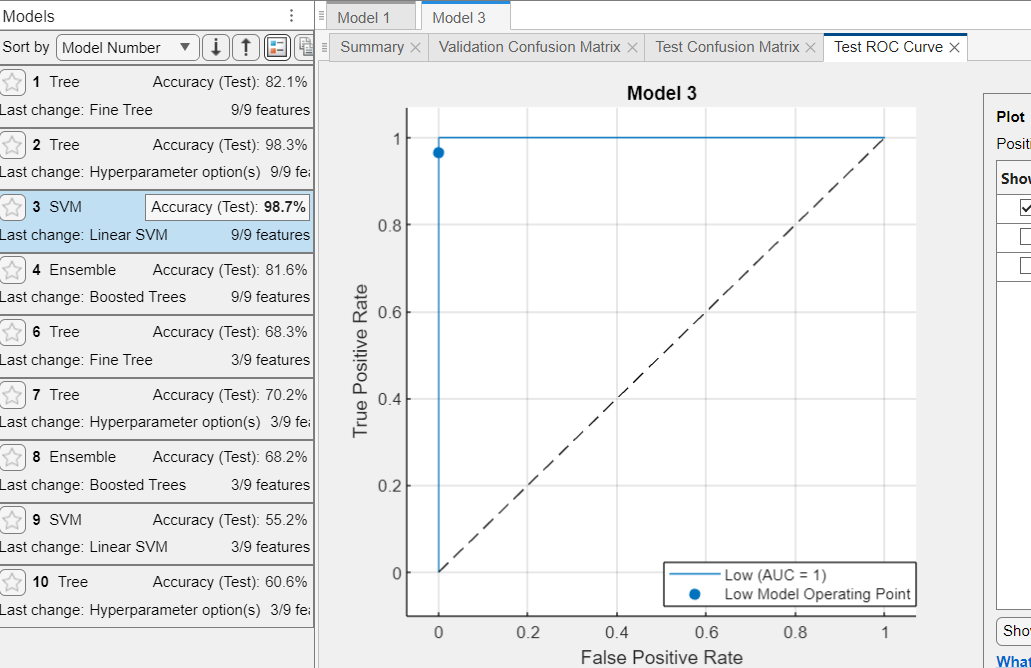

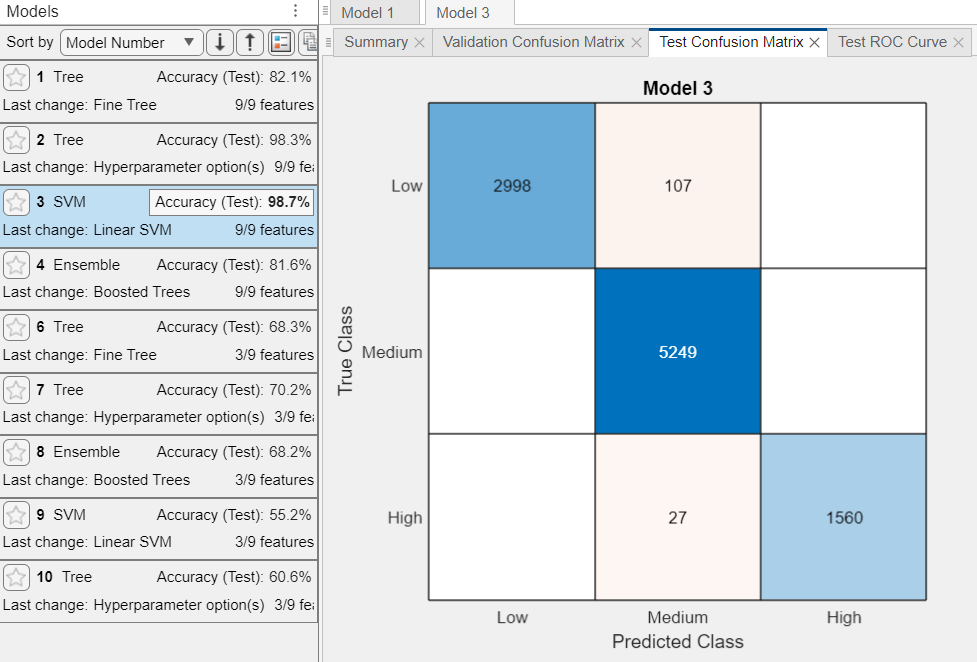

## Conclusions

Using some of groupsummary variable and variable generated from feature engineering process can give best model for predicting the Demand around Manhattan and the airports. The final model, which is linear SVM with 9 predictors give 99.5% accuracy for training and validation and 98.7% in testing. Using the model 2 with consideration of using more feature give better prediction than model 1.

This succesful model demand hopefully will enable Super Taxis to focus on high demand regions and avoid low demand ones, thus improving efficiency and increasing profits.

### Summary of model

As shown above, the model that give the best prediction is the final model. The result summary of the Classification learner app are as follow

resultsTable1

      Region            HourlyBin          PickupCount    DropoffCount    AvgDistance    AvgDuration    AvgFare    NetPickups    Demand    IsHoliday    HourOfDay
    ___________    ____________________    ___________    ____________    ___________    ___________    _______    __________    ______    _________    _________

    JFK Airport    01-Jan-2015 05:00:00         1              0             19.93             36           52          1        Medium      true           5    
    JFK Airport    01-Jan-2015 07:00:00         2              2            19.815         27.067           54          0        Medium    

      Region            HourlyBin          PickupCount    DropoffCount    AvgDistance    AvgDuration    AvgFare    NetPickups    DayofYear    IsHoliday    HourOfDay
    ___________    ____________________    ___________    ____________    ___________    ___________    _______    __________    _________    _________    _________

    JFK Airport    01-Jan-2015 00:00:00         2              0             11.71         22.525        33.75          2            1          true           0    
    JFK Airport    01-Jan-2015 01:00:00         2              0             18.25         27.183        47.25          2         

      Region            HourlyBin          PickupCount    DropoffCount    AvgDistance    AvgDuration    AvgFare    NetPickups    DayofYear    IsHoliday    HourOfDay    Demand
    ___________    ____________________    ___________    ____________    ___________    ___________    _______    __________    _________    _________    _________    ______

    JFK Airport    01-Jan-2015 00:00:00         2              0             11.71         22.525        33.75          2            1          true           0        Medium
    JFK Airport    01-Jan-2015 01:00:00         2              0  

resultsTable1 = 9x8 table
    Favorite    Model Number    Model Type     Status     Accuracy % (Validation)    Total Cost (Validation)    Accuracy % (Test)    Total Cost (Test)
    ________    ____________    __________    ________    _______________________    _______________________    _________________    _________________

     false          "1"         "Tree"        "Tested"            82.595                       6921                  82.145                1775       
     false          "2"         "Tree"        "Tested"            98.111                        751                   98.31                 168       
     false          "3"         "SVM"         "Tested"            99.525                        1

## Appendix

### Appendix 1 : Data section

#### Task 1 : Creating the taxi regions

Add zone to taxi data

Add duration to taxi data

Create the region for Pickup and Dropoff

#### Task 2 : Data Cleaning

#### Task 3 : Data Restructuring - Creating Group Summary Table

Group Summary Table include this following:

1. A categorical variable that records the 6 taxi **regions**. 

2. A datetime variable that records each **hour **of the year for each of the taxi regions.

These first two variables establish the groups for the taxi data, such that there is only one group for each combination of **region **and **hour**. The remaining features record summary statistics for each group. You must include variables for:

3. The number of taxi **pickups**.

4. The number of taxi **drop-offs**.

5. The number of **net pickups**, defined as **pickups **minus **drop-offs**.

6. The **mean or median distance** for all pickups within the group.

7. The **mean or median duration** for all pickups within the group.

8. The **mean or median fare** for all pickups within the group.

### Appendix 2 : Model Training, validation, and testing

Code for Model training, validation, and testing